% addpath('C:\Users\Elder\Documents\GitHub\EoS\Test-Scripts');


%% Image information
filenames = {'02-21-2016_02_41_02_top'
'02-21-2016_02_40_11_top'
'02-21-2016_02_39_21_top'
'02-21-2016_02_38_30_top'
'02-21-2016_02_37_39_top'
'02-21-2016_02_36_48_top'
'02-21-2016_02_35_58_top'
'02-21-2016_02_35_07_top'
'02-21-2016_02_34_16_top'
'02-21-2016_02_33_25_top'
'02-21-2016_02_32_16_top'
'02-21-2016_02_31_26_top'
'02-21-2016_02_30_35_top'
'02-21-2016_02_28_58_top'
'02-21-2016_02_28_07_top'
'02-21-2016_02_27_17_top'
'02-21-2016_02_26_26_top'
'02-21-2016_02_25_35_top'
'02-21-2016_02_24_44_top'
'02-21-2016_02_23_03_top'
'02-21-2016_02_22_12_top'
'02-21-2016_02_21_21_top'
'02-21-2016_02_20_30_top'
'02-21-2016_02_19_40_top'
'02-21-2016_02_18_49_top'
'02-21-2016_02_17_58_top'
'02-21-2016_02_16_02_top'};


imagename = filenames{i};
% imagename = '02-12-2016_21_20_17_top.fits';
econst.pixelsize = 1.44e-6;
econst.fudge = 1.837;
uconst.sigma0 = 6*pi*((671*10^-9)/(2*pi))^2;

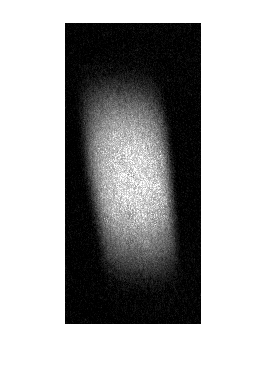

%% Load image data
data = imagedata(imagename,'crop',{'rect',271,218,135,300},'bg',{'avg',20},'plot',{0},'Nsat',630);
z_i_raw = (1:size(data.od2,1))' * econst.pixelsize;

figure;
imshow(data.od2,[0 2.5]); set(gca,'YDir','normal');

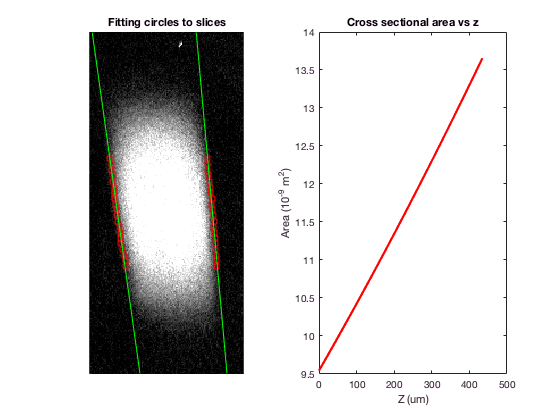

% Find cross sectional area
%ycuts = (95:5:190)';
%[xsec_area, corrected_data] = get_xsection_area(data.od2,ycuts,econst.pixelsize);

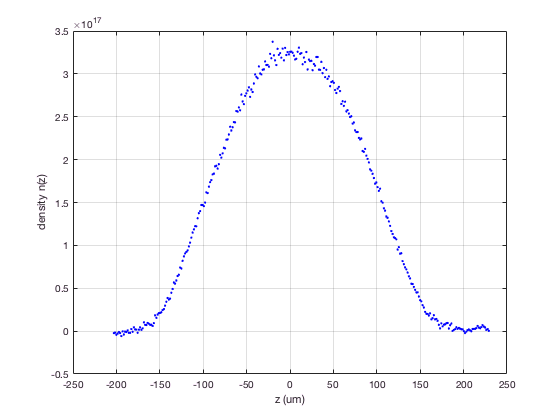

% Find center with Thomas fermi
n_z = sum(data.od2,2) ./ (xsec_area / econst.pixelsize * (uconst.sigma0 / 2)) * econst.fudge;
figure; plot(z_i_raw * 10^6, n_z,'b.'); xlabel('z (um)'); ylabel('density n(z)');
fitres = createFitTFnz(z_i_raw,n_z);
z_i = z_i_raw - fitres.x0;
figure; plot(z_i * 10^6, n_z,'b.'); xlabel('z (um)'); ylabel('density n(z)'); grid on;

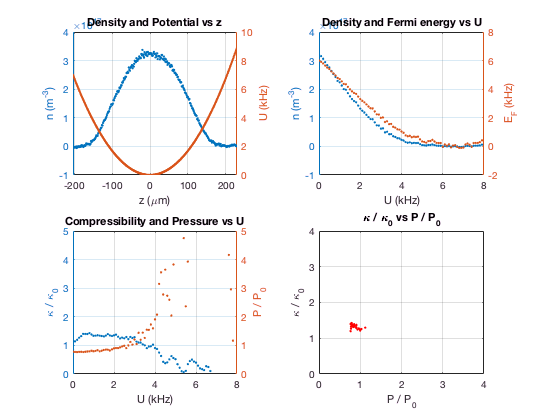

%% Get k vs P
[ k_U, P_U, U_i, EF_U, n_U ] = EoS_nz_KvsP( z_i, n_z,'plot_maxU',8,'UkHz',(0:0.1:8)','Urange',[0.1 3]);

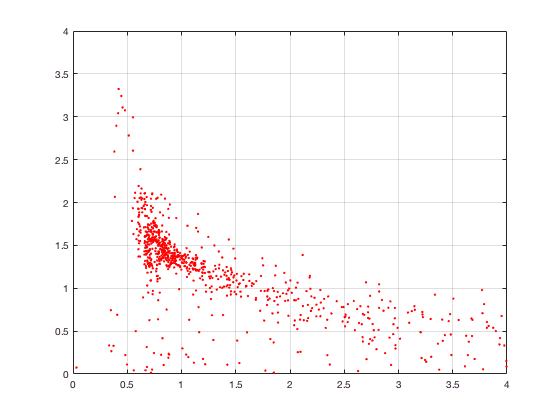

%all_kU = [];
%all_PU = [];
%all_kU = [all_kU;k_U];
%all_PU = [all_PU;P_U];
%i = i + 1;
figure;
plot(all_PU,all_kU,'r.'); xlim([0 4]); ylim([0 4]); grid on;

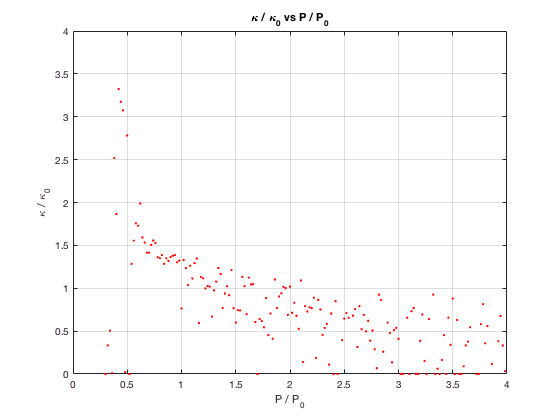

Pt_i = (0.3:0.02:4)';
kt_Pt = zeros(length(Pt_i)-1,1);
kt_Pt_err = zeros(size(kt_Pt));
whichbin = discretize(all_PU,Pt_i);
for i = 1:length(kt_Pt)
    binmem = all_kU(whichbin == i);
    if isempty(binmem), binmem = 0; end
    kt_Pt(i) = mean(binmem);
    kt_Pt_err(i) = std(binmem);
end
Pt_i = Pt_i(1:end-1);
figure; plot(Pt_i,kt_Pt,'r.'); ylim([0 4]);
title('\kappa / \kappa_0 vs P / P_0'); xlabel('P / P_0'); ylabel('\kappa / \kappa_0'); grid on;

%% Remove high frequency noise
nxy = data.od2;
nxyt = fftshift(fft2(nxy));
nxyt2 = nxyt;

% Remove a rectangle
% figure; ax = subplot(1,1,1); imshow(abs(nxyt2),[0 100]);
% [~,rect] = imcrop(ax);
% 
% for i = 1:size(nxy,2)
%     for j = 1:size(nxy,1)
%         if i > rect(1) & i < rect(1)+rect(3) & j > rect(2) & j < rect(2)+rect(4), nxyt2(j,i) = 0; end
%     end
% end

% Remove all high freq
i1 = round(size(nxy,1)/4); i2 = round(size(nxy,1)*3/4); j1 = round(size(nxy,2)/4); j2 = round(size(nxy,2)*3/4);
for i = 1:size(nxy,1)
    for j = 1:size(nxy,2)
        if ~(i>i1 & i<i2 & j>j1 & j<j2), nxyt2(i,j) = 0; end
    end
end

nxy2 = ifft2(ifftshift(nxyt2));
data.od2 = real(nxy2);

figure;
subplot(2,2,1); imshow(nxy,[0 2]); 
subplot(2,2,3); imshow(abs(nxyt),[0 100]); 
subplot(2,2,4); imshow(abs(nxyt2),[0 100]);
subplot(2,2,2); imshow(abs(nxy2),[0 2]);





